% This algorithm plots calibration curves based on a given spreadsheet's
% data to compare the measured vs nominal hardness values of four different
% calibration blocks

% Load the CSV file with specified options
opts = detectImportOptions('Lab3_Hardness_SS24_Section 6.csv', 'NumHeaderLines', 1);
data = readtable('Lab3_Hardness_SS24_Section 6.csv', opts);

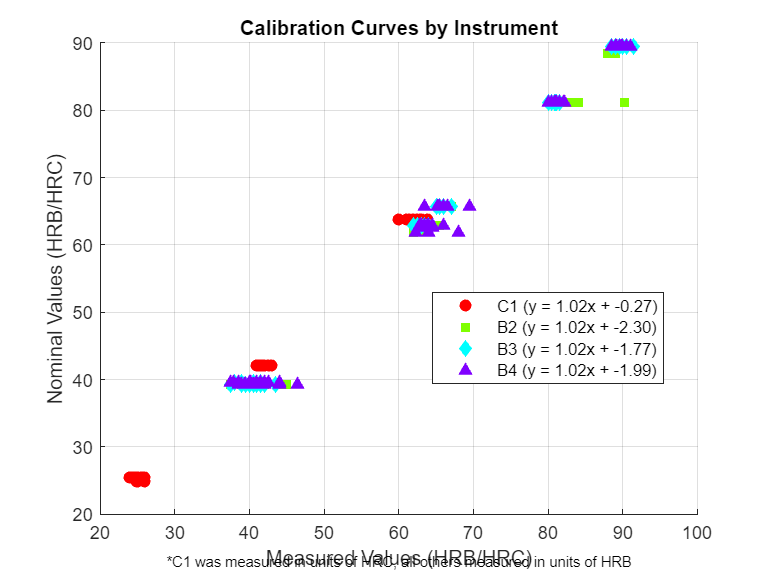


% Define scales of interest and their corresponding markers
scales = {'C1', 'B2', 'B3', 'B4'};
markers = {'o', 's', 'd', '^'}; % Changed markers for B2 and B3

% Colors for each scale
colors = hsv(length(scales)); 

% Plot calibration curves for each scale
figure; hold on;

% Initialize cell array for legend entries
legendInfo = cell(1, length(scales));

for i = 1:length(scales)
    % Filter data for the current scale
    scaleData = data(strcmp(data{:, 'Scale'}, scales{i}), :);
    
    % Sort the scale data by measured values to ensure proper plotting
    [sortedMeasured, sortIdx] = sort(scaleData{:, 4}); % Measured value
    sortedNominal = scaleData{sortIdx, 2}; % Calibration block value
    
    % Plot with unique markers and colors, without connecting the points
    scatter(sortedMeasured, sortedNominal, 36, 'Marker', markers{i}, ...
        'MarkerEdgeColor', colors(i, :), ...
        'MarkerFaceColor', colors(i, :), ...
        'DisplayName', scales{i});
    
    % Calculate the line of best fit
    coeffs = polyfit(sortedMeasured, sortedNominal, 1); % Linear fit
    
    % Create the equation string for the legend
    eqnStr = sprintf('y = %.2fx + %.2f', coeffs(1), coeffs(2));
    legendInfo{i} = sprintf('%s (%s)', scales{i}, eqnStr);
end

% Add plot details
xlabel('Measured Values (HRB/HRC)');
ylabel('Nominal Values (HRB/HRC)');
title('Calibration Curves by Instrument');

% Add legend with combined labels and equations
legend(legendInfo, 'Location', 'Best');

% Add a note at the bottom of the figure
text(0.5, -0.1, '*C1 was measured in units of HRC, all others measured in units of HRB', ...
     'HorizontalAlignment', 'center', 'Units', 'normalized', ...
     'FontSize', 8, 'FontWeight', 'normal');

grid on;

% Make sure nothing else is plotted
hold off;